# ***NEWTON'S METHOD***

% Clear all the parameters from the workspace and also clear the command window.
clear all
clc

% Define initial conditions
q0 = [[0 0 0]',[pi/2 pi/2 pi/2]'];

% Define the step-sizes we are going to test.
alpha = [1/2 1/10];

% Desired position of the end effector
x_de = [2 1 0]';

% Matrices useful for the implementation of the algorithm
syms x y z
K = [cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z]';
J = jacobian([cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z],[x,y,z]);

maxIter = 50;
errTh = 1e-6;

Figure that takes into account the magnitude of the error of the netwon's methos 

[newton.q1, newton.num_iter1, newton.err1] = newton_method(J, K, q0(:,1), x_de, maxIter, errTh);
[newton.q2, newton.num_iter2, newton.err2] = newton_method(J, K, q0(:,2), x_de, maxIter, errTh);

display(mod(newton.q1(:,newton.num_iter1),2*pi)*180/pi)

   90.0000
  270.0000
    0.0000



display(mod(newton.q2(:,newton.num_iter2),2*pi)*180/pi)

    0.0000
   90.0000
  270.0000



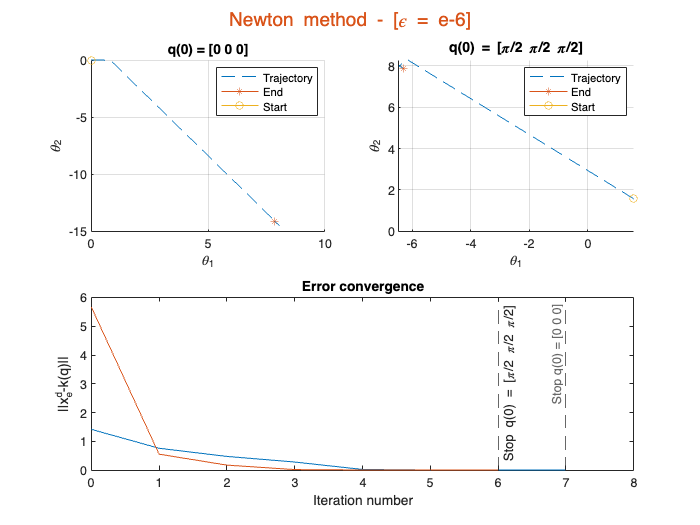

figure()
sgt = sgtitle('Newton method - [\epsilon = e-6]');
sgt.FontSize = 15;
%sgt.FontWeight = 'bold';
sgt.Color = '#D95319';
sgt.Margin = 4;

subplot(2,2,1)
hold on
plot3(newton.q1(1,:),newton.q1(2,:),newton.q1(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(newton.q1(1,newton.num_iter1),newton.q1(2,newton.num_iter1),newton.q1(3,newton.num_iter1),'Marker','*','DisplayName','End')
plot3(newton.q1(1,1),newton.q1(2,1),newton.q1(3,1),'Marker','o','DisplayName','Start')
title('q(0) = [0 0 0]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(newton.q2(1,:),newton.q2(2,:),newton.q2(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(newton.q2(1,newton.num_iter2),newton.q2(2,newton.num_iter2),newton.q2(3,newton.num_iter2),'Marker','*','DisplayName','End')
plot3(newton.q2(1,1),newton.q2(2,1),newton.q2(3,1),'Marker','o','DisplayName','Start')

title('q(0) = [\pi/2 \pi/2 \pi/2]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,[3,4])
plot(0:newton.num_iter1, newton.err1(1,1:(newton.num_iter1+1)))
hold on
plot(0:newton.num_iter2, newton.err2(1,1:(newton.num_iter2+1)))
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
xline(newton.num_iter1,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','left');
xline(newton.num_iter2,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
xlim([0 max(newton.num_iter1,newton.num_iter2)+1]);
title('Error convergence')

### NEWTON'S FUNCTION

function [q, nIter, err] = newton_method(J, k, q0, x_de, maxIter, errTh)
% --------------------  OUTPUT  --------------------
% q: vector of the solution evaluated at each step;
% nIter: number of the stopping interation;
% err: vector of the error evaluated at each step; 

    % Initialization    
    syms x y z
    qTmp = zeros(3,maxIter);
    errTmp = zeros(1, maxIter);
    nIter = 0;

    % Evaluation of the error at first iteration (we consider error norm)
    qTmp(: , 1) = q0;    
    kTmp = subs(k,{x,y,z},qTmp(:,1)');
    errTmp(1) = norm(x_de-kTmp);

    j = 2;
    while (nIter < maxIter)
        nIter = j-1;
        % Jacobian at previus iteration
        Jtmp = subs(J,{x,y,z},qTmp(:,j-1)');
        % Evaluation of the pseudo-inverse - this handles the
        % non-invertible case
        Jinv=pinv(Jtmp);
        % Solution update
        qTmp(:,j) = qTmp(:,j-1) + Jinv*(x_de-kTmp);
        % K(q) at current iteration
        kTmp = subs(k,{x,y,z},qTmp(:,j)');
        % K(q) at current iteration
        errTmp(j) = norm(x_de-kTmp);

        % Early stopping strategy based on error's improvement
        if abs(errTmp(j)-errTmp(j-1)) < errTh
            break  
        end
        j = j+1;
    end
    % Considering as output only nonzero elements
    q = qTmp(:,1:nIter+1); 
    err = errTmp(1:nIter+1);
end
